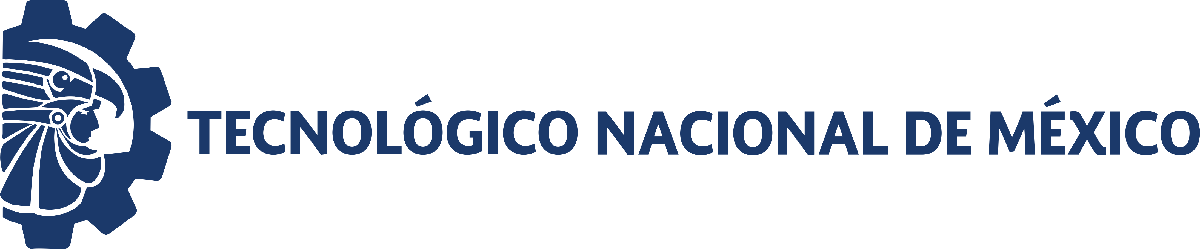                                 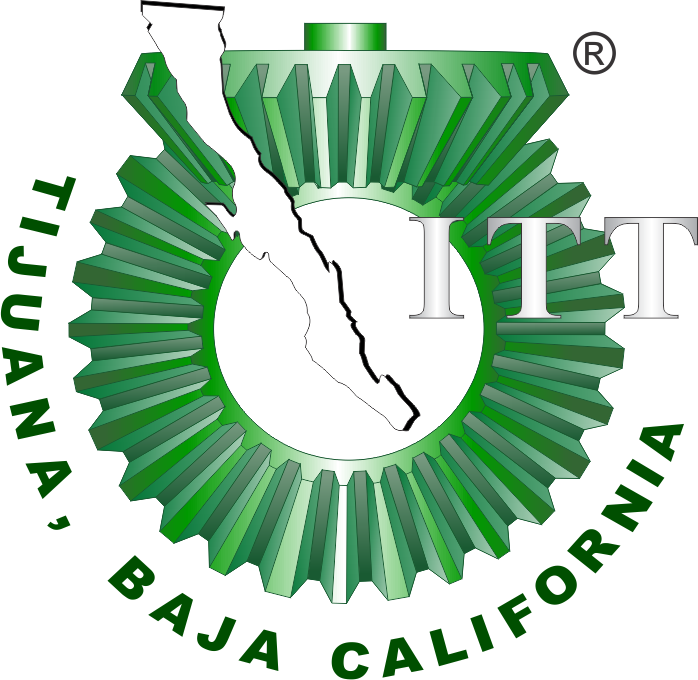

# Práctica Cuatro: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

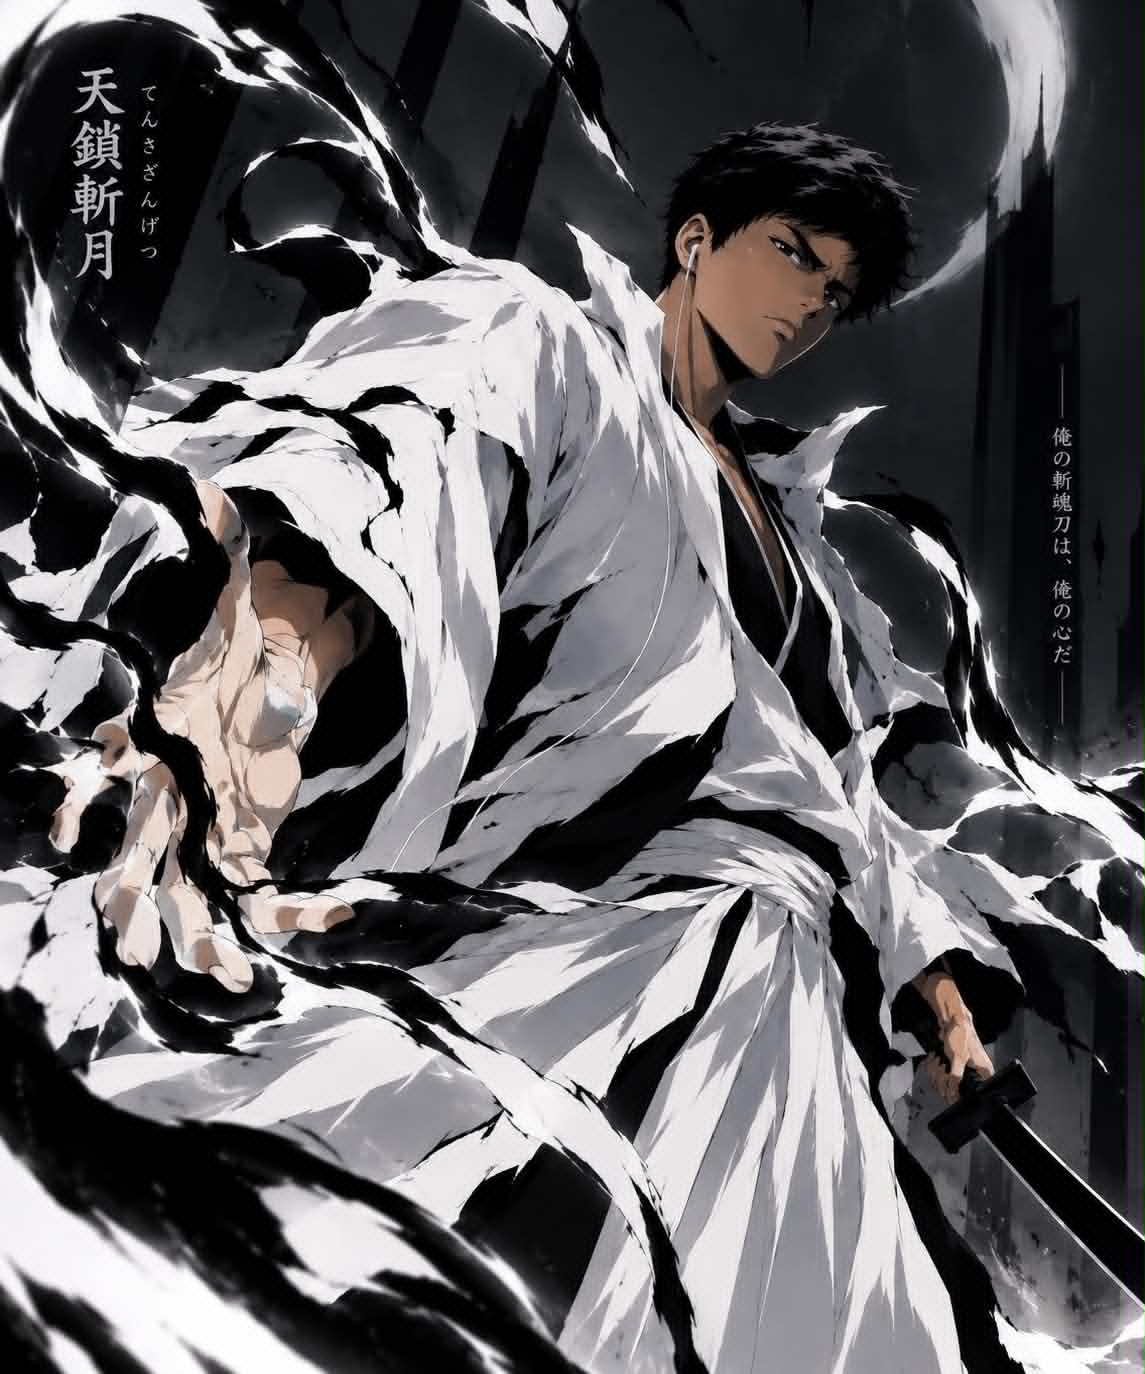

Nombre del alumno: **Neltzon Farid Garcia Altamirano**

Número de control: **23212194**

Correo institucional: **l23212194tijuana.tecnm.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('MPSFP4NFGA.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep ='1e-3';

## Respuesta al escalón

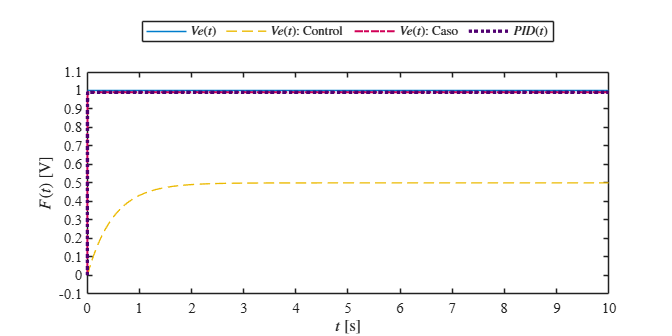

X = sim('MPSFP4NFGA.slx',parameters);
plotsignals(X.t,X.Ve,X.Gcas,X.Gcon,X.PID,'Control y caso')

## Funcion: Respuesta de la simulacion

function plotsignals(t,Ve,Gcas,Gcon,PID,signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
ctrl1 = [0, 125, 204]/255;
ctrl2 = [235,185,0]/255;
ctrl3 = [209,0,86]/255;
ctrl4 = [80,0,113]/255;
order = [ctrl1;ctrl2;ctrl3;ctrl4]; colororder(order)

if signal == "Control y caso"
    plot(t,Ve,'-','Linewidth',0.5,'Color',ctrl1)
    plot(t,Gcas,'--','Linewidth',1,'Color',ctrl2)
    plot(t,Gcon,'-.','Linewidth',1.5,'Color',ctrl3)
    plot(t,PID,':','Linewidth',2.5,'Color',ctrl4)
    L = legend('$Ve(t)$','$Ve(t)$: Control','$Ve(t)$: Caso','$PID(t)$');
end

set(L,'interpreter','latex','location','northoutside','orientation','horizontal')

xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')

xlim([0 10]); xticks(0:1:15)
ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

exportgraphics(gcf,[signal,'.matlab.pdf'],'contenttype','vector')
end